# Analise das distribuições no disco rotor

### descida com velocidade de avanço

clc
clear
close all

mass_payload = 20;
density = 1.225;
vehicle_position = [0; 0; 0];
vehicle_velocity = [10; 0; -20];
vehicle_orientation = [0; 0; 0];

Nb = 4;
Span = 1;
RootBladeDistance = 0.1;
root_theta = 10;
twist_rate = 0;
root_chord = 0.17;
lambda_chord = 1;
disk_area = pi * (Span - RootBladeDistance)^2;
induced_velocity = -1.5;

RPM = 500;

azimutal_points = 500;
No_elements = 500;

blade_integrator = 'Trapezoidal'; % 'Boole'; 'Rectangle'; 'Simpson';

sim_init_rotor_simulation
[F_rotor, T_rotor, rotor_distribution_data] = compute_rotor_force(SIM, VEHICLE, ROTOR, BLADE, ATMOSPHERE)

F_rotor =    32.2798
   -0.0000
  924.7682


T_rotor =    93.1263
   -0.0000
 -150.5162


rotor_distribution_data =   RotorAzimutalDistribution with properties:

    blade_distribution_data: [1×500 BladeDistribution]
          azimutal_position: [500×1 double]


azimutal_points_to_plot = [90 180 360];
colors = {'b', 'k', 'r', 'm'}; % Azul, preto, vermelho, roxo

#### Velocidade Tangencial

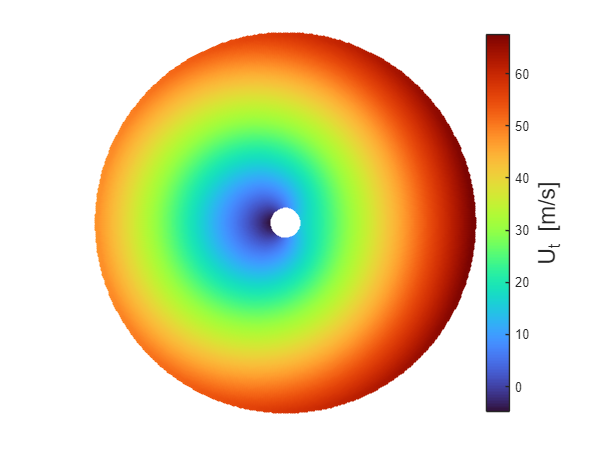

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).U_T;
end
polarPlot(azimutes, rho, values, "", "U_t [m/s]", "./studies/rotor_analysis/sim_D/U_T.eps")

#### Velocidade Radial

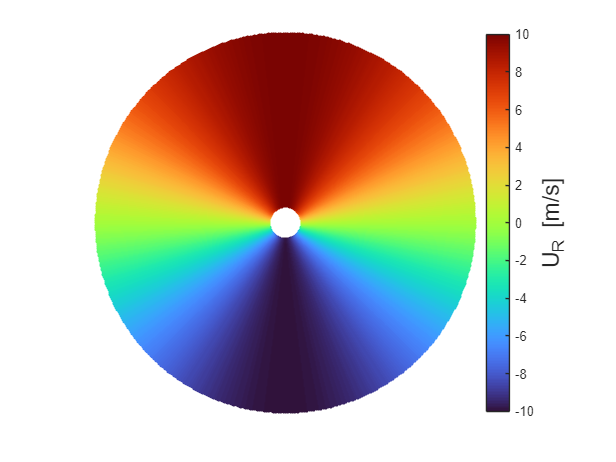

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).U_R;
end
polarPlot(azimutes, rho, values, "", "U_R [m/s]", "./studies/rotor_analysis/sim_D/U_R.eps")

#### Velocidade Vertical

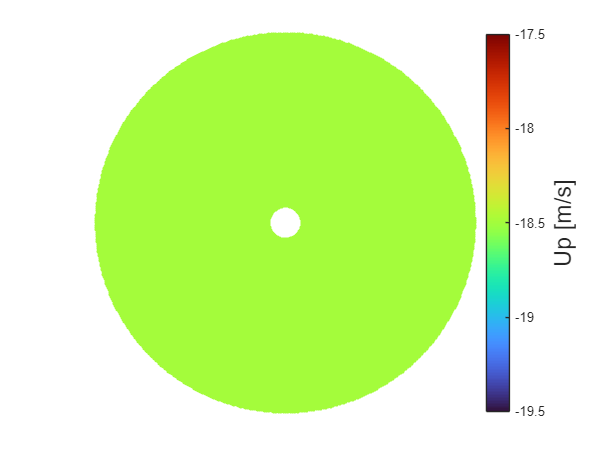

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).U_P;
end
polarPlot(azimutes, rho, values, "", "Up [m/s]", "./studies/rotor_analysis/sim_D/U_P.eps")

#### Modo de escoamento

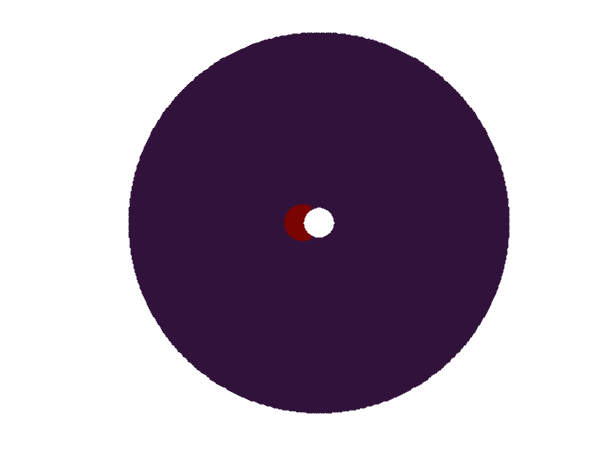

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).flow_mode;
end
polarPlot(azimutes, rho, values, "", "", "./studies/rotor_analysis/sim_D/flow_mode_10.eps")

#### Número de Reynolds

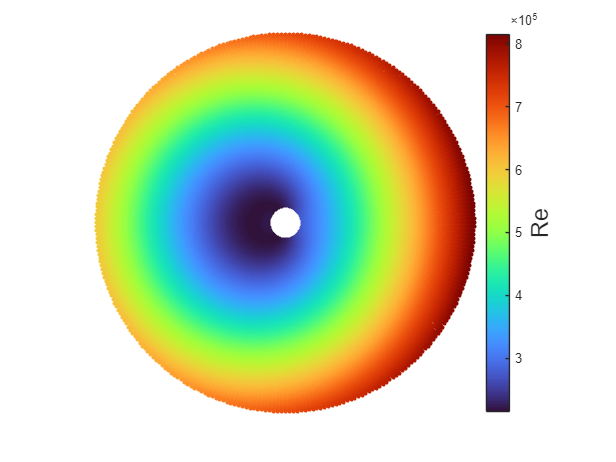

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).Re;
end
polarPlot(azimutes, rho, values, "", "Re", "./studies/rotor_analysis/sim_D/Re.eps")

#### Número de Mach

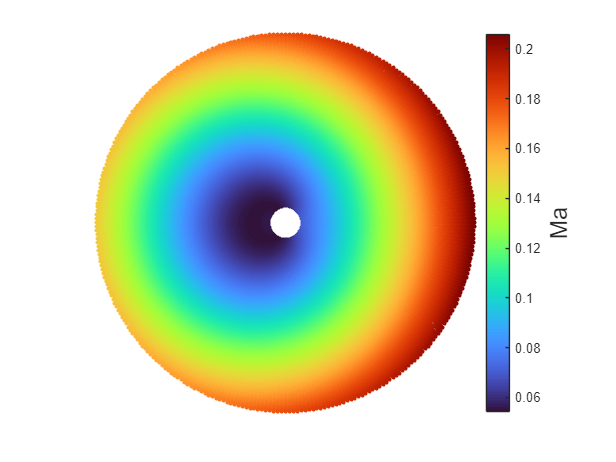

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).Ma;
end
polarPlot(azimutes, rho, values, "", "Ma", "./studies/rotor_analysis/sim_D/mach.eps")

#### Ângulo de picada

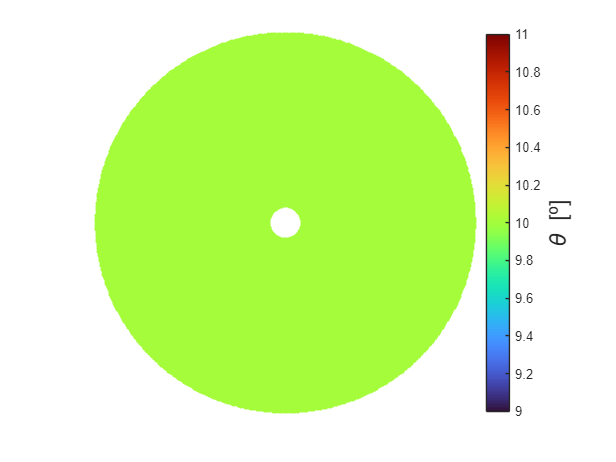

for i=1:length(azimutes)
    values(i, :) = BLADE.theta;
end
polarPlot(azimutes, rho, values, "", "\theta [º]", "./studies/rotor_analysis/sim_D/theta.eps")

#### Ângulo de incidência

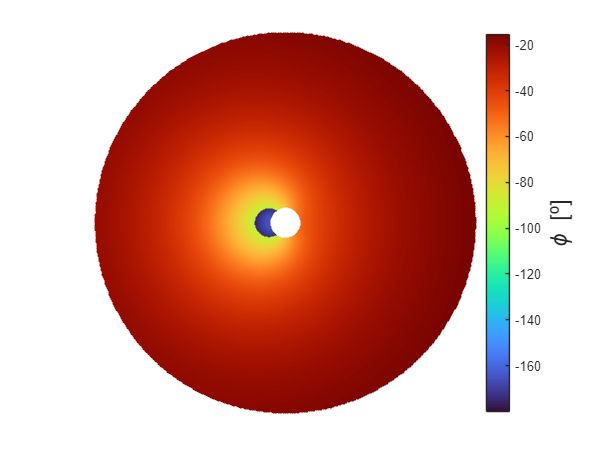

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).phi;
end
polarPlot(azimutes, rho, values, "", "\phi [º]", "./studies/rotor_analysis/sim_D/phi.eps")

#### Ângulo de ataque

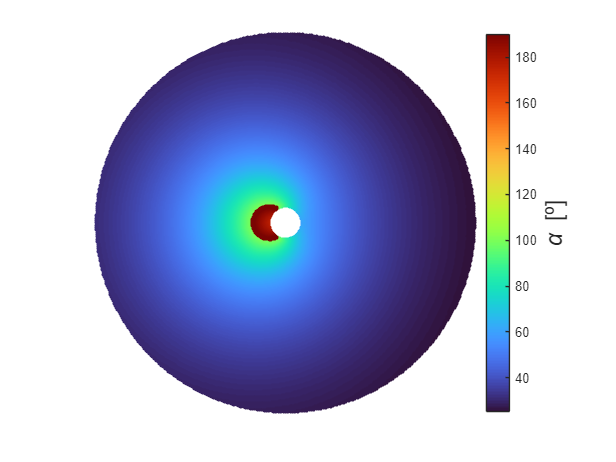

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).alpha;
end
polarPlot(azimutes, rho, values, "", "\alpha [º]", "./studies/rotor_analysis/sim_D/alpha.eps")

#### Coeficiente de Sustentação

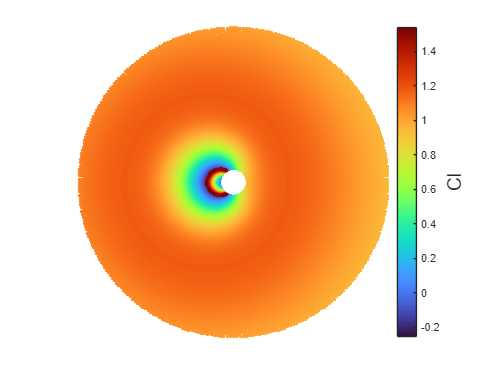

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).Cl;
end
polarPlot(azimutes, rho, values, "", "Cl", "./studies/rotor_analysis/sim_D/cl.eps")

#### Coeficiente de Arrasto

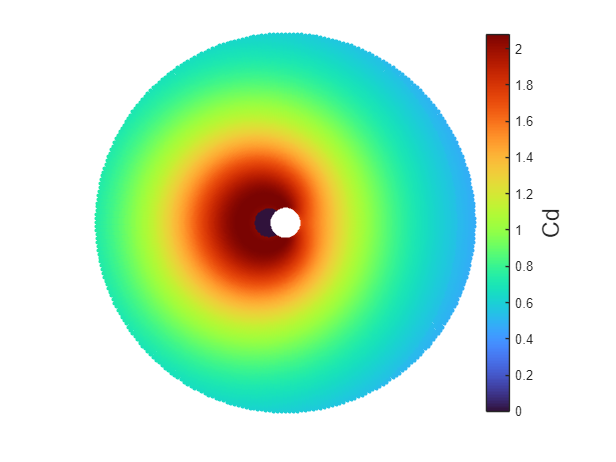

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).Cd;
end
polarPlot(azimutes, rho, values, "", "Cd", "./studies/rotor_analysis/sim_D/cd.eps")

#### Força em X - referencial do aerodinâmico

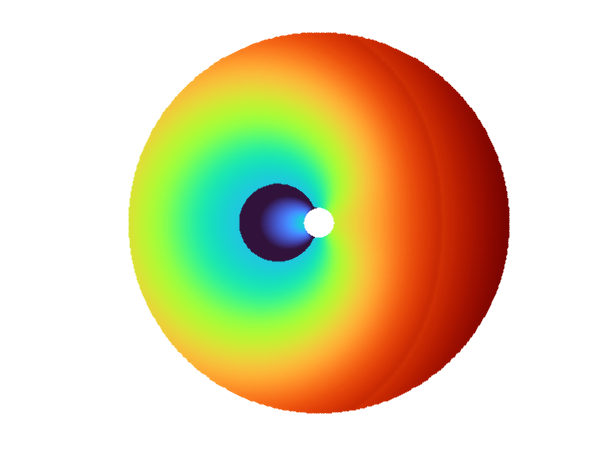

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_a_x;
end
polarPlot(azimutes, rho, values*BLADE.dy, "", "F_x [N]","./studies/rotor_analysis/sim_D/dFx_a.eps")

#### Força em Y - referencial do aerodinâmico

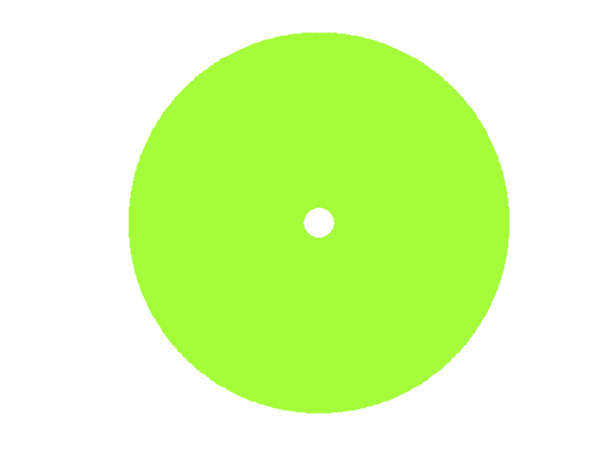

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_a_y;
end
polarPlot(azimutes, rho, values*BLADE.dy, "", "F_y [N]", "./studies/rotor_analysis/sim_D/dFy_a.eps")

#### Força em Z - referencial do aerodinâmico

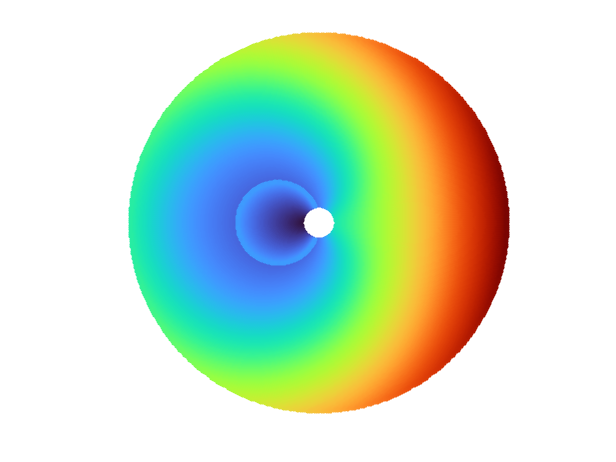

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_a_z;
end
polarPlot(azimutes, rho, values*BLADE.dy, "", "F_z [N]", "./studies/rotor_analysis/sim_D/dFz_a.eps")

#### Força em X - referencial do rotor

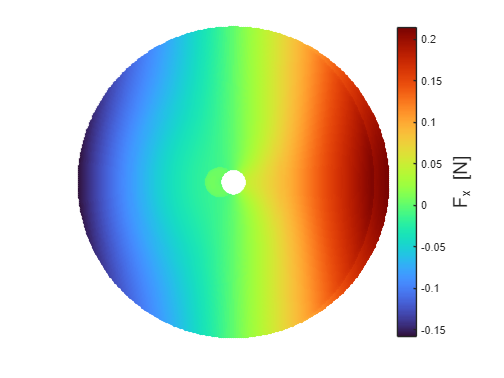

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_i_x;
end
polarPlot(azimutes, rho, values*BLADE.dy, "", "F_x [N]", "./studies/rotor_analysis/sim_D/dFx_r.eps")

#### Força em Y - referencial do rotor

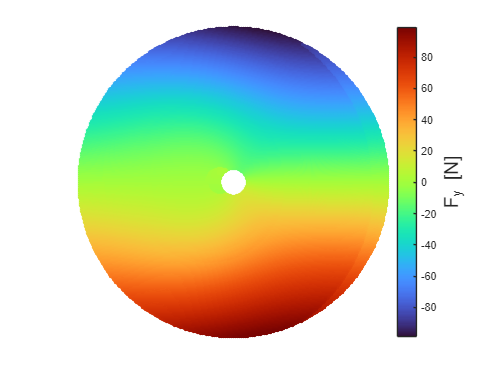

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_i_y;
end
polarPlot(azimutes, rho, values, "", "F_y [N]", "./studies/rotor_analysis/sim_D/dFy_r.eps")

#### Força em Z - referencial do rotor

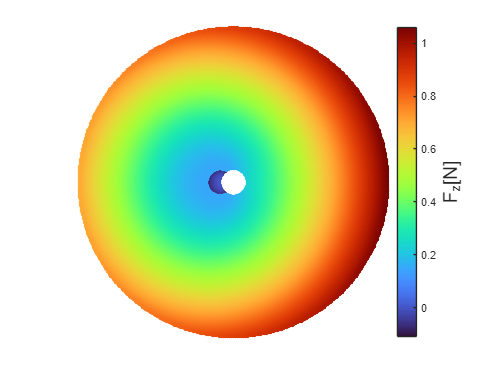

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_i_z;
end
polarPlot(azimutes, rho, values*BLADE.dy, "", "F_z[N]", "./studies/rotor_analysis/sim_D/dFz_r.eps")

#### Torque em X - referencial do rotor

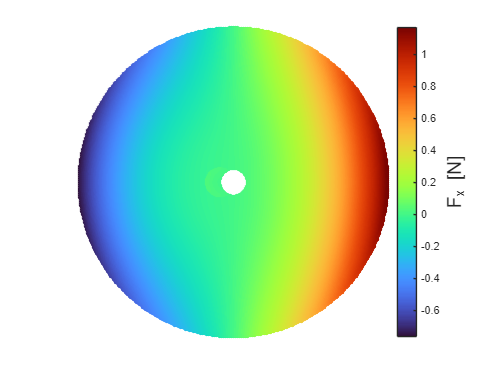

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dT_r_x;
end
polarPlot(azimutes, rho, values*BLADE.dy, "", "T_x [N]", "./studies/rotor_analysis/sim_D/dTx_r.eps")

#### Torque em Y - referencial do rotor

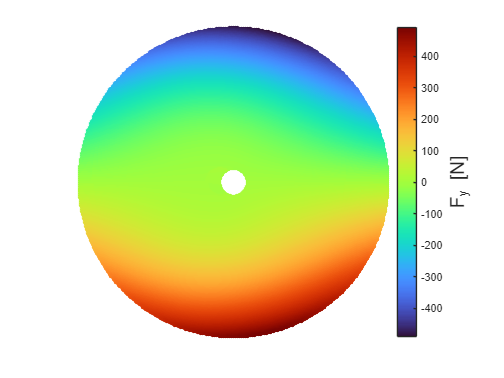

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dT_r_y;
end
polarPlot(azimutes, rho, values, "", "F_y [N]", "./studies/rotor_analysis/sim_D/dTy_r.eps")

#### Torque em Z - referencial do rotor

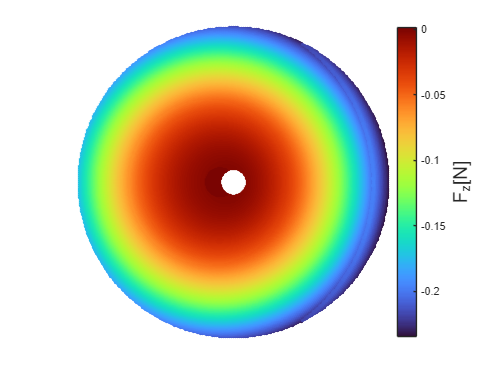

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dT_r_z;
end
polarPlot(azimutes, rho, values*BLADE.dy, "", "F_z[N]", "./studies/rotor_analysis/sim_D/dTz_r.eps")